load MotorY_NoControl.mat
t_Y_NC = out.tout;
input_Y_NC = out.simout4;
error_Y_NC = out.simout5;
CE_Y_NC = out.simout6;
output_Y_NC = out.simout7

  timeseries

  Common Properties:
            Name: 'Output (Feedback)'
            Time: [134x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [134x1 double]
        DataInfo: 

CE_Y_NC = (11.4/255)*CE_Y_NC;


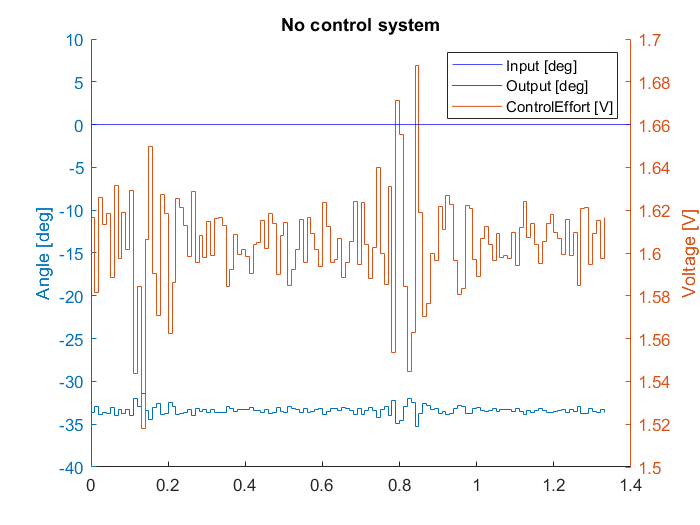

clf;
hold on
yyaxis left
yline(0,'b')
plot(output_Y_NC)
ylabel('Angle [deg]')
ylim([-40 10])


yyaxis right
plot(CE_Y_NC)
ylabel('Voltage [V]')

title('No control system')
legend('Input [deg]','Output [deg]','ControlEffort [V]')

hold off